% ===== 多级带级间加热的轴流式透平机测试代码 =====
% 系统参数
N_stage = 3;                            % 级数
pressure_drop_ratio = 0.015;            % 级间压力损失比例 (1.5%)

% 第一级透平机入口参数 (高压天然气)
T_in1 = 325;                            % 入口温度 (K) - 约52°C
P_in1 = 8e6;                            % 入口压力 (Pa) - 8MPa
m = 8.5;                                % 天然气质量流量 (kg/s)
c_in1 = 45;                             % 入口速度 (m/s)

% 各级透平机参数
expansion_ratio_list = [2.8, 2.3, 1.9]; % 膨胀比分配 (逐级递减)
eta_ts_list = [0.89, 0.87, 0.85];       % 等熵效率

% 各级加热器参数 根据比热容确定液体种类
T_hot_in_list = [473.15, 473.15, 473.15]; % 热源入口温度 (K)
m_dot_hot_list = [10, 10, 10];          % 热源质量流量 (kg/s)
cp_hot_list = [2000, 2000, 2000];       % 热源比热容 [J/(kg·K)]
P_hot_list = [3e5, 3e5, 3e5];           % 热源压力 (Pa)

% 各级换热器参数
U_list = [45, 45, 45];                  % 传热系数 [W/(m²·K)]
A_list = [180, 180, 180];               % 传热面积 (m²)
HX_type_list = {'counterflow', 'counterflow', 'counterflow'}; % 逆流换热器

% 气体常数 
R = 287;                              % 气体常数 [J/(kg·K)]
k = 1.4;                                % 绝热指数
Cp = 1005;                              % 定压比热容 [J/(kg·K)]

% 运行多级膨胀机系统
system_result = multi_stage_turbine_system(...
    N_stage, T_in1, P_in1, m, c_in1, ...
    expansion_ratio_list, eta_ts_list, ...
    T_hot_in_list, m_dot_hot_list, cp_hot_list, P_hot_list, ...
    U_list, A_list, HX_type_list, ...
    R, k, Cp, pressure_drop_ratio);


--- 第 1 级计算开始 ---
透平机1计算: 入口温度=325.00K, 入口压力=8000000.00Pa
单级轴流式透平机设计结果:
出口温度: 251.28 K
出口压力: 2857142.86 Pa
温降: 73.72 K
输出功率: 629726.81 W
等熵焓降: 83242.14 J/kg
实际效率: 22.61%
透平机1输出: 出口温度=251.28K, 出口压力=2857142.86Pa, 输出功率=629.73kW
级间压力损失: 42857.14Pa
下一级加热器入口: 温度=251.28K, 压力=2814285.71Pa

--- 第 2 级计算开始 ---
加热器2计算: 工质入口=251.28K, 热源入口=473.15K
加热器2输出: 工质出口=374.95K, 热源出口=420.33K, 加热量=1056.47kW
透平机2计算: 入口温度=374.95K, 入口压力=2814285.71Pa
单级轴流式透平机设计结果:
出口温度: 305.87 K
出口压力: 1223602.48 Pa
温降: 69.08 K
输出功率: 590149.06 W
等熵焓降: 79803.79 J/kg
实际效率: 18.38%
透平机2输出: 出口温度=305.87K, 出口压力=1223602.48Pa, 输出功率=590.15kW
级间压力损失: 18354.04Pa
下一级加热器入口: 温度=305.87K, 压力=1205248.45Pa

--- 第 3 级计算开始 ---
加热器3计算: 工质入口=305.87K, 热源入口=473.15K
加热器3输出: 工质出口=399.11K, 热源出口=433.32K, 加热量=796.53kW
透平机3计算: 入口温度=399.11K, 入口压力=1205248.45Pa
单级轴流式透平机设计结果:
出口温度: 342.27 K
出口压力: 634341.29 Pa
温降: 56.84 K
输出功率: 485574.91 W
等熵焓降: 67207.60 J/kg
实际效率: 14.21%
透平机3输出: 出口温度=342.27K, 出口压力=634341.29Pa, 输出功率=485.57kW

========== 多级轴流透平机系统性能摘要 ==========
系统级数

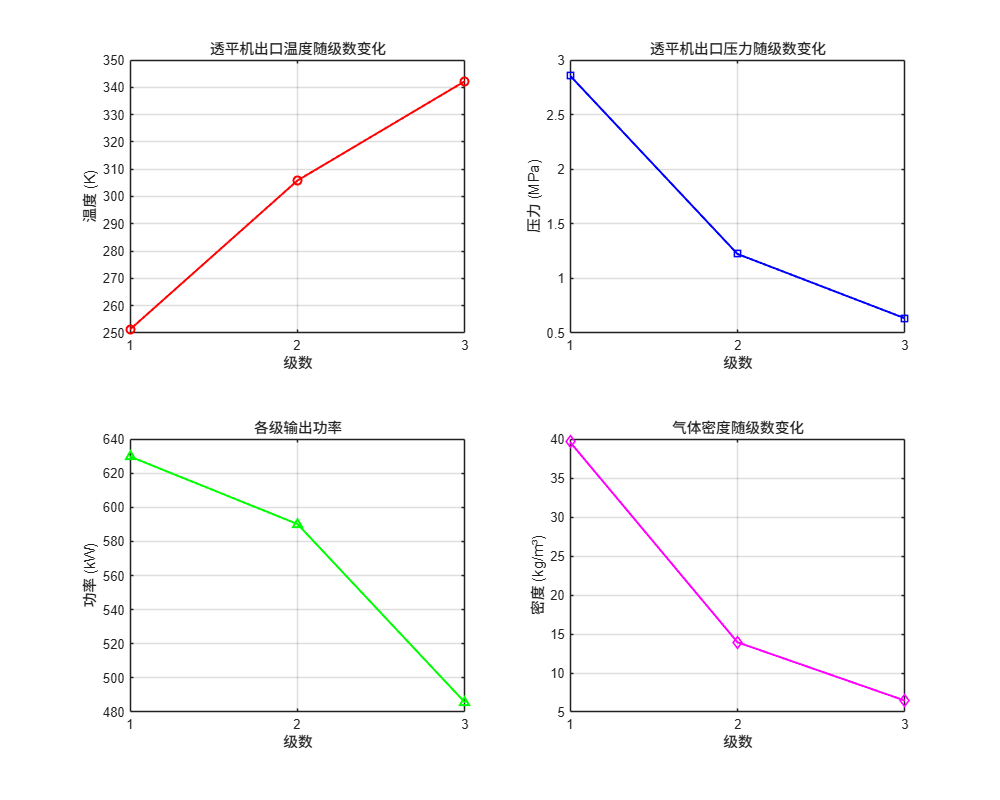

% 提取物性参数变化
stage_num = 1:N_stage;
T_out_turbine = cellfun(@(x) x.T_out, system_result.turbine_results); % 透平出口温度
P_out_turbine = cellfun(@(x) x.P_out, system_result.turbine_results); % 透平出口压力
power_per_stage = cellfun(@(x) x.power, system_result.turbine_results); % 各级功率
heat_input_per_stage = system_result.heater_results.Q; % 各级加热量

% 计算气体密度变化 (ρ = P/(RT))
rho = P_out_turbine./(R * T_out_turbine);

% 绘制物性参数变化曲线
figure('Position', [100, 100, 1000, 800]);
subplot(2,2,1)
plot(stage_num, T_out_turbine, 'ro-', 'LineWidth', 1.5, 'MarkerSize', 6)
title('透平机出口温度随级数变化');
xlabel('级数'); ylabel('温度 (K)'); grid on;
xticks(1:N_stage);

subplot(2,2,2)
plot(stage_num, P_out_turbine/1e6, 'bs-', 'LineWidth', 1.5, 'MarkerSize', 6)
title('透平机出口压力随级数变化');
xlabel('级数'); ylabel('压力 (MPa)'); grid on;
xticks(1:N_stage);

subplot(2,2,3)
plot(stage_num, power_per_stage/1000, 'g^-', 'LineWidth', 1.5, 'MarkerSize', 6)
title('各级输出功率');
xlabel('级数'); ylabel('功率 (kW)'); grid on;
xticks(1:N_stage);

subplot(2,2,4)
plot(stage_num, rho, 'md-', 'LineWidth', 1.5, 'MarkerSize', 6)
title('气体密度随级数变化');
xlabel('级数'); ylabel('密度 (kg/m³)'); grid on;
xticks(1:N_stage);

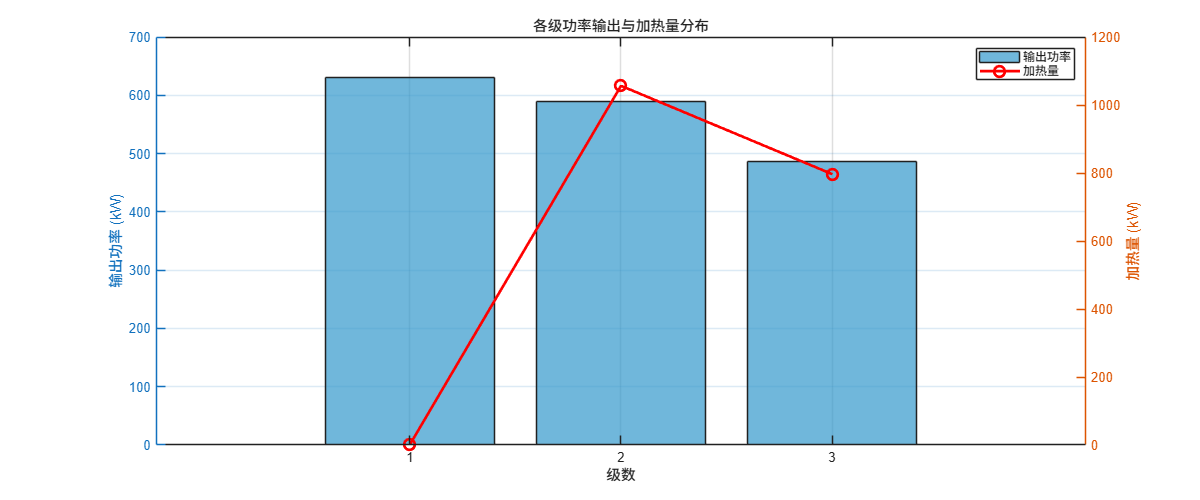


% 绘制功率和加热量分布图
figure('Position', [100, 100, 1200, 500]);
yyaxis left
bar(stage_num, power_per_stage/1000, 'FaceColor', [0.2, 0.6, 0.8], 'FaceAlpha', 0.7);
ylabel('输出功率 (kW)');
yyaxis right
plot(stage_num, heat_input_per_stage/1000, 'r-o', 'LineWidth', 2, 'MarkerSize', 8);
ylabel('加热量 (kW)');
title('各级功率输出与加热量分布');
xlabel('级数'); grid on;
legend('输出功率', '加热量', 'Location', 'northeast');
xticks(1:N_stage);